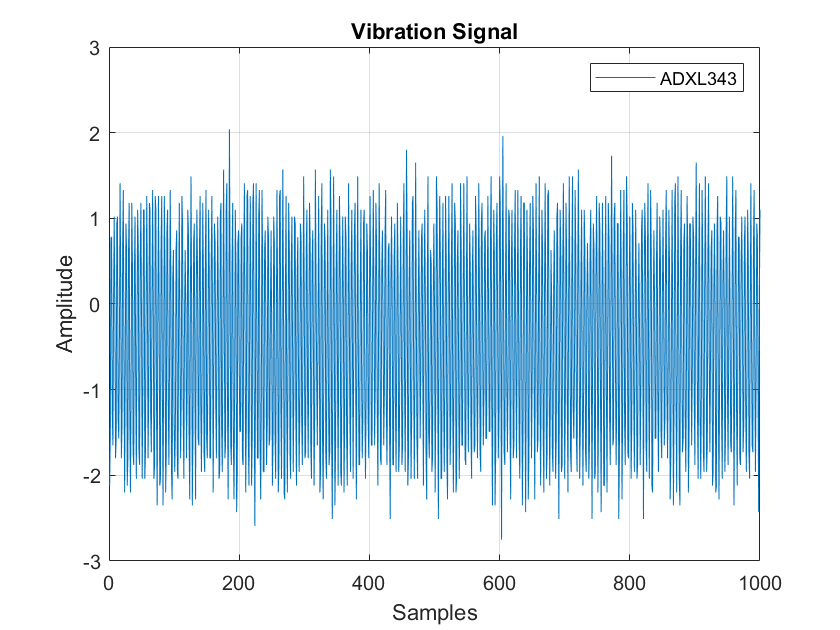

Fs = 1000;          % Sampling frequency (100 kHz)                   
T = 1/Fs;             % Sampling period       
t = 0:T:1-T;        % Time vector

plot(adxl343_550hz)

% yticks([0.1 0.2 1.5])
legend('ADXL343');
title('Vibration Signal')
xlabel('Samples')
ylabel('Amplitude')
grid on

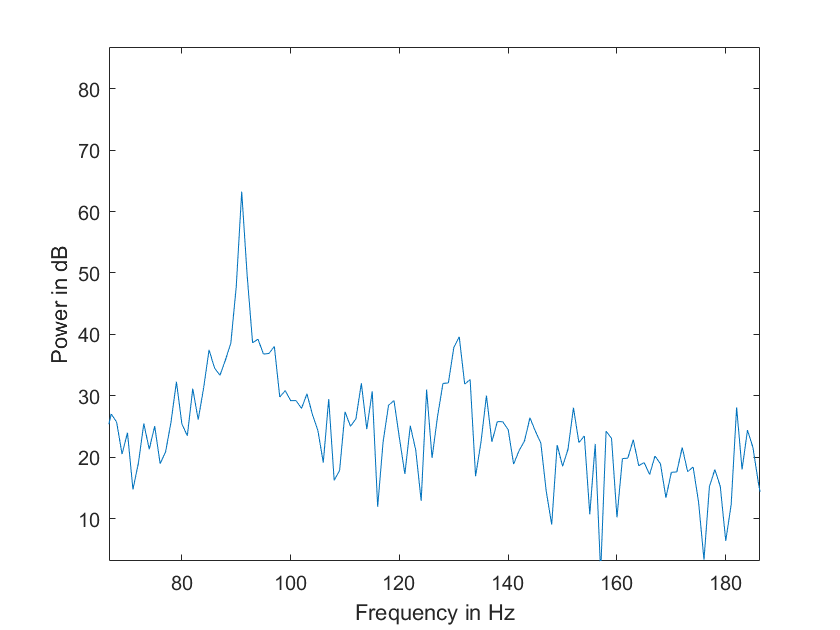


NFFT = length(mpu6050_1300hz); %length of the Signal (FFT Signal Points)
[P,F] = periodogram(mpu6050_1300hz,[],NFFT,Fs,'power');

plot (F,10*log10(P));
xlabel('Frequency in Hz')
ylabel ('Power in dB')

xlim([66.6 186.3])
ylim([3.1 86.8])